clear;
clc;

%heart disease variables stored in array form
gender = [0,0];                 %Assign gender with empty array, male=1, 
chest_pain_type = [0,0,0,0];    %female=0 for person with heart disease
fbs = [0,0];
ecg = [0,0,0];
exang = [0,0];
slope = [0,0,0];                %Assign number of variables with empty array  
ca = [0,0,0,0];                 %with corresponsing attributes for person with
thal = [0,0,0];                 %heart disease

%healthy variables stored in array form
gender_h = [0,0];                   %Assign gender with 2 variable, male=1, 
chest_pain_type_h = [0,0,0,0];      %female=0 for healthy person
fbs_h = [0,0];                      % 1 is first 0 is second element count
ecg_h = [0,0,0];                    % 
exang_h = [0,0];                    %Assign number of variables with empty array 
slope_h = [0,0,0];                  %with corresponding attributes for healthy person
ca_h = [0,0,0,0];
thal_h = [0,0,0];

[heart_disease,healthy,T]=positive();    
% sorting for person positive for heart disease and healthy people from heart disease mat file 

chest_pain_type =fourvariable(heart_disease,chest_pain_type,3,1,2,3,4);   %for person with heart disease, chest pain type with 
fbs = twovaraible(heart_disease,fbs,6,1,0);                               %user defined function four variable cases with 
ecg= threevaraible(heart_disease,ecg,7,0,1,2);                            %corresponding attributes
exang = twovaraible(heart_disease,exang,9,1,0);
slope =  threevaraible(heart_disease,slope,11,1,2,3);
ca=fourvariable(heart_disease,ca,12,0,1,2,3);
thal= threevaraible(heart_disease,thal,13,3,6,7);
gender = twovaraible(heart_disease,gender,2,1,0);
%counting of variables for heart disease array from column 3,6,7,9,11,12,13 and 2 and store them in
%an array functions like two variable and three variables and four
%variables are user defined functions that must be downloaded 

chest_pain_type_h=fourvariable(healthy,chest_pain_type_h,3,1,2,3,4); %for healthy person, chest pain type with user defined function 
fbs_h = twovaraible(healthy,fbs_h,6,1,0);                            %four variable cases with corresponding attributes
ecg_h=threevaraible(healthy,ecg_h,7,0,1,2);
exang_h = twovaraible(healthy,exang_h,9,1,0);
slope_h =  threevaraible(healthy,slope_h,11,1,2,3);
ca_h=fourvariable(healthy,ca_h,12,0,1,2,3);
thal_h=threevaraible(healthy,thal_h,13,3,6,7);
gender_h = twovaraible(healthy,gender_h,2,1,0);
%counting of variables for healthy array from column 3,6,7,9,11,12,13 and 2 and store them in
%an array functions like two variable and three variables and four
%variables are user defined functions that must be downloaded 

[avg,sdv] = calculationstdev_mean(heart_disease(:,[1 4 5 8 10])); %calculation of average and standard deviation of those with heart disease
[avg_h,sdv_h] = calculationstdev_mean(healthy(:,[1 4 5 8 10]))  ; %calculation of average and standard deviation of those that are healthy

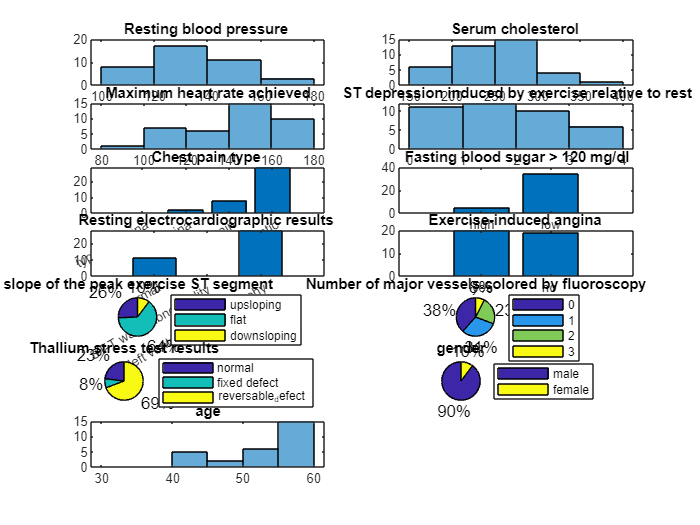

figure(1) %Plots of attributes contributing to ones with heart disease
plotting(heart_disease,chest_pain_type,fbs,ecg,exang,slope,ca,thal,gender);

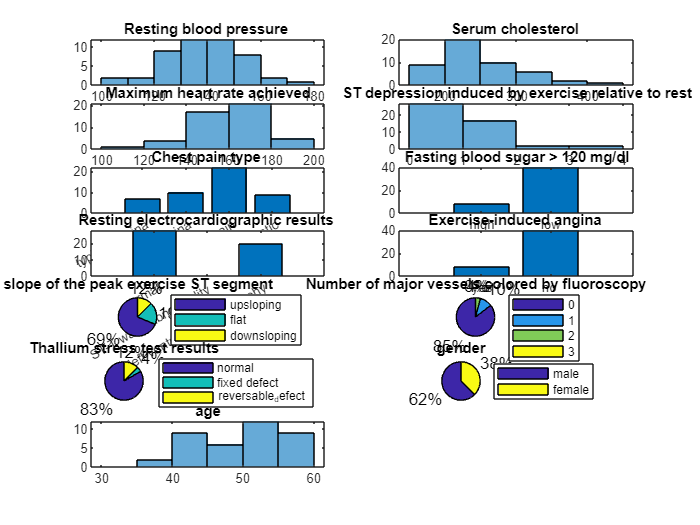


figure(2) %Plots of attributes contributing to ones that are healthy
plotting(healthy,chest_pain_type_h,fbs_h,ecg_h,exang_h,slope_h,ca_h,thal_h,gender_h);

prob_heartdisease = probablity(gender,T); %calculation of probability suffering from heart disease of a certain gender put in a array
prob_healthy = probablity(gender_h,T); %calculation of probability suffering from heart disease to the healthy ones of a certain gender put in a array

theory question

- **Do older people have a higher risk of heart disease? What is the difference in the distribution of ages for people with and without heart disease?**

As seen from figure 1, bottom right graph (subplot 6,2,12), older people in the age group of 55 to 60 have a relatively higher risk of getting a heart disease compared to other age groups (e.g. in age group 40-45, 45-50, 50-55), which have low or no risk of heart disease. The mean age for old people without heart disease is 56 years while the mean age for old people without heart disease is 52 years ,  the distribution for heart disease is more closer than the healthy as heart disease have a lower standard deviation than the heart disease.based on the mean and standard deviation we can see that older people have a higher risk of heart disease because the mean for heart disease is higher and the distribution are closer to each other

- **Which gender has a higher risk of getting heart disease? What is the probability for a male/female to get heart disease?**

As seen from figure 1, bottom left graph(subplot 6,2,11), 90% of those suffering from heart diseases are male. Therefore, it can be concluded that males are at higher risk of getting a heart disease.male has higher chance to get heart disease compared to female as  based on the overall population of 88 people, male with heart disease has the highest probability of 39.7% while female with heart disease has the lowest probability of 4.5%

- **What kind of test results show more indication that a patient has heart disease? What is the difference in the test results for patients with and without heart disease?**

Lowered ST depression induced by exercise relative to rest,  having asymptomatic type chest pain higher left ventricular hypertrophy,lower number of major vessel coloured by fluoroscopy flat slope of peak exercise ST segment,  increased reversible defect of thallium stress test and as presence of exercise-induced angina indicates the likelihood of getting a heart disease. However, symptoms only illustrate the likelihood of heart disease but not sufficient to confirm a diagnosis.

 Looking at the graphs , a significant difference between heart disease and healthy   in the resting blood pressure , serum cholesterol, maximum heart rate  . For the resting blood pressure , heart disease have  a lower range at 120- 140 while healthy have a higher resting blood pressure. We also can say that people with heart disease have a higher serum cholestrol than those without it , they also have a higher maximum heart rate compare to healthy and a higher ST depresstion compare to the healthy

the mean values for heart attack and healthy  supports the point above that people with heart disease have a higher mean value for serum choloestrol and maximum heart rate and st depression.

SUMMARY OF CONTRIBUTIONS

patrick (2100904)                 100%        three and four variable function , report wrting and analysis

Ng Yeow Kiang(2201308)   100%      two variable funciton and positive function , report wrting and analysis

jovie(2202225)                     100%      probability and calauclation stdev_mean function, report wrting and analysis

valarie(2202067)              100%    write the main code and compile all function together to make it work,  report wrting and analysis                   

Tuck Siang(2202322)              100%  plotting function, report wrting and analysis